# Opgave 1: Sandsynlighedsregning

**En virksomhed producerer et elektrisk apparat. Inden apparaterne forlader fabrikken**

**kvalitetstjekkes de. Ved kvalitetskontrollen godkendes 86% af apparaterne.**

**De ikke-godkendte apparater kan have to typer fejl: Fejl A og fejl B. En opgørelse viser, at 42%**

**af de ikke-godkendte apparater har fejl A og 72% har fejl B.**


$$\begin{array}{l}
\mathrm{AP}=\mathrm{virkende}\;\mathrm{Apparat}\\
\overline{\;\mathrm{AP}} =\mathrm{ikke}\;\mathrm{virkende}\;\mathrm{Apparat}\\
\mathrm{FA}=\mathrm{fejl}\;A\\
\mathrm{FB}=\mathrm{fejl}\;B
\end{array}$$



$$\begin{array}{l}
\mathrm{Pr}\left(\mathrm{AP}\right)=0\ldotp 86\\
\mathrm{Pr}\left(\mathrm{FA}|\overline{\;\mathrm{AP}} \right)=0\ldotp 42\\
\mathrm{Pr}\left(\mathrm{FB}|\overline{\;\mathrm{AP}} \right)=0\ldotp 72
\end{array}$$


**a) Hvor mange procent af de producerede apparater har fejl.**


$$\mathrm{Pr}\left(\overline{\;\mathrm{AP}} \right)=1-\mathrm{Pr}\left(\mathrm{AP}\right)=1-0\ldotp 86=0\ldotp 14$$


14% sandsynlighed

**b) Hvor mange procent af de producerede apparater har fejl A?**


$$\mathrm{Pr}\left(\mathrm{FA}\right)=\mathrm{Pr}\left(\mathrm{FA}|\overline{\;\mathrm{AP}} \right)\cdot \;\mathrm{Pr}\left(\overline{\;\mathrm{AP}} \right)=0\ldotp 42\cdot 0\ldotp 14=0\ldotp 0588$$


5.8% har fejl A

**c) Hvor mange procent af de producerede apparater har både fejl A og fejl B?**


$$\mathrm{Pr}\left(\mathrm{FB}\right)=\mathrm{Pr}\left(\mathrm{FB}|\overline{\;\mathrm{AP}} \right)\cdot \;\mathrm{Pr}\left(\overline{\;\mathrm{AP}} \right)=0\ldotp 72\cdot 0\ldotp 14=0\ldotp 1008$$



$$\mathrm{Pr}\left(\mathrm{FA}\cap \mathrm{FB}\right)=\mathrm{Pr}\left(\mathrm{FA}\right)+\mathrm{Pr}\left(\mathrm{FB}\right)-\mathrm{Pr}\left(\overline{\;\mathrm{AP}} \right)=\left(\mathrm{Pr}\left(\mathrm{FA}|\overline{\;\mathrm{AP}} \right)+\mathrm{Pr}\left(\mathrm{FB}|\overline{\;\mathrm{AP}} \right)-1\right)\cdot \mathrm{Pr}\left(\overline{\;\mathrm{AP}} \right)\;=\left(0\ldotp 42+0\ldotp 72-1\right)\cdot \;0\ldotp 14=0\ldotp 0196$$


1.96% har både fejl A og fejl B

**d) Hvis et apparat har fejl A, hvad er sandsynligheden for at apparatet også har fejl B?**


$$\mathrm{Pr}\left(\mathrm{FB}|\mathrm{FA}\right)=\frac{\mathrm{Pr}\left(\mathrm{FA}\cap \mathrm{FB}\right)}{\mathrm{Pr}\left(\mathrm{FA}\right)}=\frac{0\ldotp 0196}{0\ldotp 0588}=0\ldotp 3333$$


33.33% sandsynlighed for at et apparat har B hvis det også har A

# Opgave 2: Stokastiske variable

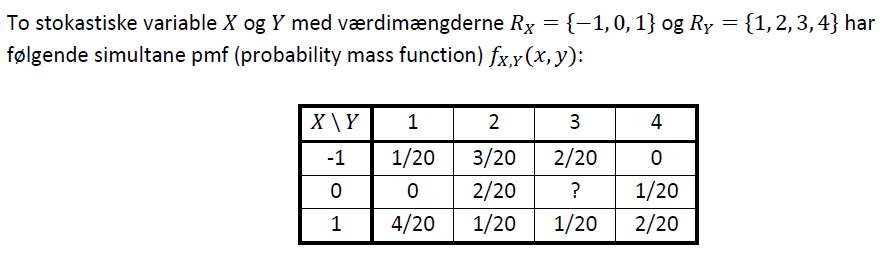

**a) Bestem sandsynligheden **$\mathrm{Pr}\left(X=0\cap Y=3\right)$

Vi ved at alle værdier lagt sammen skal give 1, derfor kan vi lægge alle værdier sammen og isolere vores variabel

syms x;
summationOfMatrix= (1/20)+(3/20)+(2/20)+(0)+(0)+(2/20)+x+(1/20)+(4/20)+(1/20)+(1/20)+(2/20);
X0_Y3 = solve(summationOfMatrix==1,x)

$$X0\_Y3 = \frac{3}{20}$$


$$\mathrm{Pr}\left(X=0\cap Y=3\right)=\frac{3}{20}$$


**b) Bestem de marginale pmf’er (probability mass functions) fX (x) og fY(y) for de stokastiske**

**variable X og Y**


$$f_{x}(x) = \left\{ 
\matrix{
\frac{6}{20} & , for & x = -1 \cr
\frac{6}{20} & , for & x = 0 \cr
\frac{8}{20} & , for & x = 1 \cr

}$$
    
$$f_{y}(y) = \left\{ 
\matrix{
\frac{5}{20} & , for & y = 1 \cr
\frac{6}{20} & , for & y = 2 \cr
\frac{6}{20} & , for & y = 3 \cr
\frac{3}{20} & , for & y = 4 \cr

}$$


**c) Bestem middelværdierne E[X] og E[Y] af de stokastiske variable X og Y**

Xminus1=[(1/20) (3/20) (2/20) (0)];
X0=[(0) (2/20) (3/20) (1/20)];
Xplus1=[(4/20) (1/20) (1/20) (2/20)];

Y1=[(1/20) 0 (4/20)];
Y2=[(3/20) (2/20) (1/20)];
Y3=[(2/20) (3/20) (1/20)];
Y4=[0 (1/20) (2/20)];


$$E\left\lbrack X\right\rbrack =\sum_{x=-1}^1 x\cdot f_x \left(x\right)\;$$


EX=((sum(Xminus1)*-1)+(sum(X0)*0)+(sum(Xplus1)*1))

EX = 0.1000


$$E\left\lbrack Y\right\rbrack =\sum_{y=1}^4 y\cdot f_y \left(y\right)$$


EY=((sum(Y1)*1)+(sum(Y2)*2)+(sum(Y3)*3)+(sum(Y4)*4))

EY = 2.3500

middelværdien for X er 0.10 og middelværdien for Y er 2.35

**d) Bestem sandsynligheden **$\mathrm{Pr}\left(X\le 0\;\;|Y\le 3\right)$

læg alle gyldige sandsynligheder sammen


$$\begin{array}{l}
\mathrm{Pr}\left(X\le 0\;\cap \;Y\le 3\right)=\mathrm{Pr}\left(X=0|Y=3\right)+\mathrm{Pr}\left(X=0|Y=4\right)+\mathrm{Pr}\left(X=-1|Y=3\right)+\mathrm{Pr}\left(X=-1|Y=4\right)=\frac{3}{20}+\frac{1}{20}+\frac{2}{20}+0=\frac{6}{20}=0\ldotp 300\\
\mathrm{Pr}\left(Y\le 3\right)=\mathrm{Pr}\left(Y=3\right)+\mathrm{Pr}\left(Y=4\right)=\frac{6}{20}+\frac{3}{20}=\frac{9}{20}=0\ldotp 450\\
\mathrm{Pr}\left(X\le 0\;\;|Y\le 3\right)=\frac{\mathrm{Pr}\left(X\le 0\;\cap \;Y\le 3\right)}{\mathrm{Pr}\left(Y\le 3\right)}=\frac{0\ldotp 300}{0\ldotp 450}=0\ldotp 6667
\end{array}$$


Sandsynligheden ligger på 66.7%

# Opgave 3: Stokastiske processer

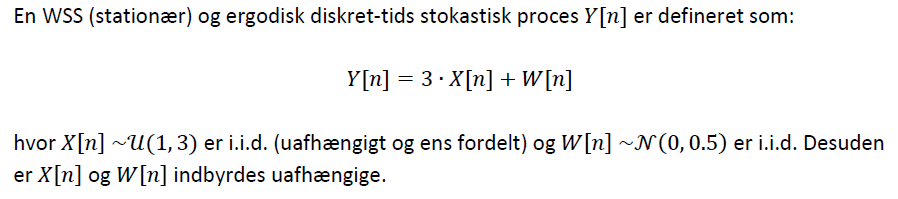

**a) Plot tre realisationer af processen Y[n], hvor der medtages 10 samples af Y[n]. Brug en**

**tilfældighedsgenerator og vis med kode (Matlab, Maple, Prime, Python el.lign.) hvordan**

**realisationen er fremkommet. I Matlab kan rand() og randn() benyttes.**

n=1:10

n =      1     2     3     4     5     6     7     8     9    10


Xn =     1.3104    1.0013    1.5672    2.1016    2.7418    1.0845    2.8094    1.2619    2.6675    2.6009


yn =     4.3903    3.0726    4.9539    6.5073    8.3122    3.5411    8.7314    3.8931    8.2623    8.2974


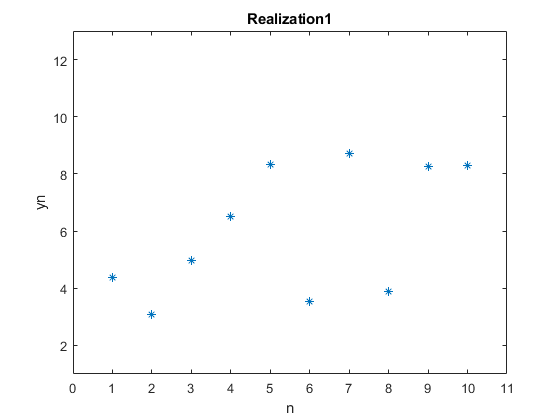

Xn =     1.9798    2.3897    1.8228    1.0696    1.5857    2.6029    1.6930    1.1666    2.0222    1.7337


yn =     6.3092    7.4316    5.8708    3.6171    4.8517    7.8705    5.4895    3.8188    6.0747    5.6490


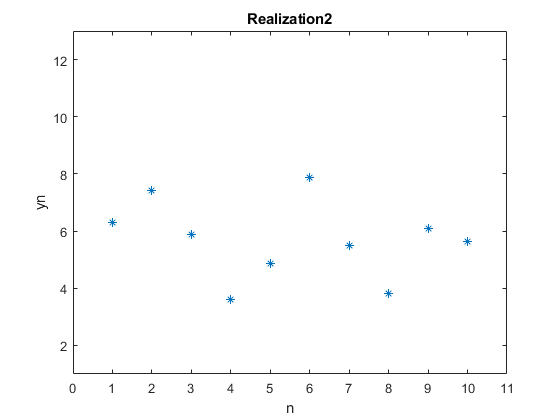

Xn =     2.0308    2.0890    2.2129    2.5209    2.7107    1.7657    1.1693    2.4677    1.6640    2.6795


yn =     6.2781    6.6812    6.7269    7.6274    8.5720    5.3193    3.8513    7.7701    5.2105    8.2284


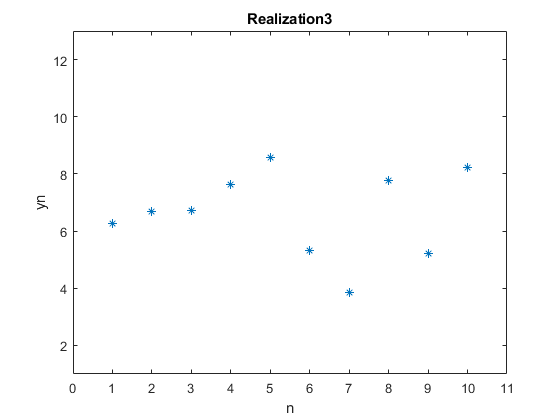

for i=1:3
    Xn=(3-1)*rand(1,10)+1
%     Xn=(rand(1,10)*3)+1;
    Wn=(rand(1,10)*0.5);
    yn=3*Xn+Wn
    figure;
    plot(n,yn,'*')
    axis([0,11,1,13])
    xlabel('n')
    ylabel('yn')
    title(['Realization',num2str(i)])
end

Der bruges en tilfældighedsgenerator med normalfordeling til de to fordelinger. processorne er indsat i en forloop således at der kan laves 3 forskellige version(realizationer) af vores process. 

**b) Bestem ensemble middelværdien og variansen for processen Y[n]. Vis desuden med**

**mellemregninger, hvordan resultatet er fremkommet.**

middelværdi for kontinueret uniform er $\frac{a+b}{2}\;$ 

middelværdi for standard normalfordeling er $\mu \;\;$ 

så formlen ser således ud


$$E\left\lbrack \mathrm{Yn}\right\rbrack =3\cdot \;E\left\lbrack \mathrm{Xn}\right\rbrack +E\left\lbrack \mathrm{Wn}\right\rbrack =3\cdot \;\frac{a+b}{2}+\mu \;=3\cdot \;\frac{1+3}{2}+0=3\cdot \;\frac{4}{2}=\frac{12}{2}=6$$


ensemble mean: 2

**c) Opskriv et udtryk og udregn ensemble variansen for processen y(t).**

Variansen for en kontinueret uniformfordeling er $\frac{{\left(b-a\right)}^2 }{12}$

Variansen for en standard normalfordeling er $\sigma {\;}^2$

Når en konstant ganges på variansen skal den opløftes i 2


$$\mathrm{var}\left(\mathrm{Yn}\right)=3^2 \cdot \;\mathrm{var}\left\lbrack \mathrm{Xn}\right\rbrack +\mathrm{var}\left\lbrack \mathrm{Wn}\right\rbrack =3^2 \cdot \;\frac{{\left(b-a\right)}^2 }{12}+\sigma {\;}^2 =3^2 \cdot \;\frac{{\left(3-1\right)}^2 }{12}+0\ldotp 5=\frac{9\cdot 4}{12}+0\ldotp 5=\frac{36}{12}+\frac{6}{12}=\frac{42}{12}=\frac{21}{6}=3\ldotp 5$$


ensemble var: $3\ldotp 5$

**c) Bestem auto-korrelationen **$R_{\mathrm{yy}} \left(\tau \;\right)$** for processen Y[n] for tids-lag **$\tau \;$** = 0, 1, 2, og 3. Dvs.**

**værdierne **$R_{\mathrm{yy}} \left(0\;\right)$**, **$R_{\mathrm{yy}} \left(1\;\right)$**, **$R_{\mathrm{yy}} \left(2\;\right)$** og **$R_{\mathrm{yy}} \left(3\;\right)$** skal beregnes. Vis desuden med mellemregninger,**

**hvordan resultaterne er fremkommet.**

Det er i opgaven givet at processen er ergodisk og WSS. Dette betyder at uanset ved hvilken tid så forventes processens mean at være det samme.

I det at tau er en tidsforskel kan vi derfor antage at den ikke har nogen effekt på vores process. Dette betyder at for alle processer hvor tau ikke er 0. Kan vi forvente at middelværdien er den samme og kan derfor skrive udtrykkende op således.


$$\begin{array}{l}
R_{\mathrm{yy}} \left(n,n+\tau \;\right)=E\left\lbrack Y\left(n\right)\cdot Y\left(n+\tau \;\right)\right\rbrack =R_{\mathrm{yy}} \left(\tau \;\right)\\
R_{\mathrm{yy}} \left(1\right)=E\left\lbrack Y\left(n\right)\cdot Y\left(n+1\right)\right\rbrack =R_{\mathrm{yy}} \left(2\right)=E\left\lbrack Y\left(n\right)\cdot Y\left(n+2\right)\right\rbrack =R_{\mathrm{yy}} \left(3\right)=E\left\lbrack Y\left(n\right)\cdot Y\left(n+3\right)\right\rbrack =6\cdot 6=36\\
R_{\mathrm{yy}} \left(0\right)=E\left\lbrack Y\left(n\right)\cdot Y\left(n+0\right)\right\rbrack =E\left\lbrack {Y\left(n\right)}^2 \right\rbrack 
\end{array}$$


For R(0) bliver vi nød til at gøre noget andet. I det at vi får $E\left\lbrack {Y\left(n\right)}^2 \right\rbrack$, hvilket er en værdi vi ikke kender kan vi bruge formlen for varians til at udregne $E\left\lbrack {Y\left(n\right)}^2 \right\rbrack$.


$$\begin{array}{l}
\mathrm{Var}\left(Y\left(n\right)\right)=E\left\lbrack {Y\left(n\right)}^2 \right\rbrack -E{\left\lbrack Y\left(n\right)\right\rbrack }^2 \Rightarrow \mathrm{Var}\left(Y\left(n\right)\right)+E{\left\lbrack Y\left(n\right)\right\rbrack }^2 =E\left\lbrack {Y\left(n\right)}^2 \right\rbrack \\
R_{\mathrm{yy}} \left(0\right)=E\left\lbrack {Y\left(n\right)}^2 \right\rbrack =\mathrm{Var}\left(Y\left(n\right)\right)+E{\left\lbrack Y\left(n\right)\right\rbrack }^2 =3\ldotp 5+\left(6\cdot 6\right)=39\ldotp 5
\end{array}$$


Til sidst ender vi med disse resultater:


$$\begin{array}{l}
R_{\mathrm{yy}} \left(0\right)=39\ldotp 5\\
R_{\mathrm{yy}} \left(1\right)=R_{\mathrm{yy}} \left(2\right)=R_{\mathrm{yy}} \left(3\right)=36
\end{array}$$


# Opgave 4: Statistik

**En flødebolle-producent laver flødeboller, som skal veje 30.0 gram. Producenten får besøg af**

**fødevarekontrollen, som tilfældigt udtager 12 flødeboller til kontrolvejning. De 12 flødeboller**

**vejer:**

maalinger=[30.09 28.78 31.01 27.02 30.11 29.35 28.37 29.65 27.71 30.58 28.06 29.04];

**a) Lav et Q-Q plot af målingerne. Er målingerne normalfordelte (svaret skal begrundes)?**

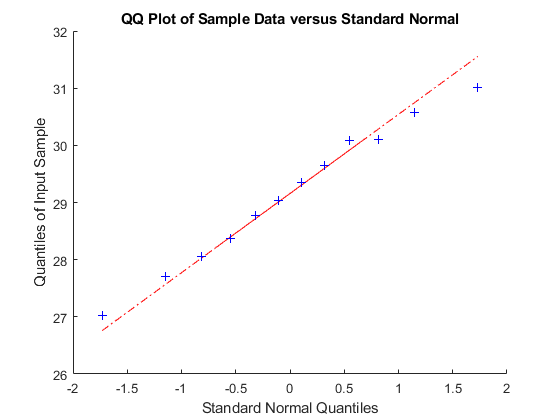

figure;
qqplot(maalinger)

Målingerne er på en tilnærmestvis retlinje og kan derfor antages at være normalfordelt

**b) Hvilken test-statistik skal bruges til at teste om flødebollerne overholder den lovede**

**vægt?**

Student t-test

**c) Opstil en nul-hypotese og en alternativ hypotese for testen.**


$$\begin{array}{l}
H_0 :\mu {\;}_0 =30\ldotp 0g\;,\mathrm{Maskinen}\;\mathrm{laver}\;\mathrm{flødeboller}\;\mathrm{rigtig}\\
H_0 :\mu {\;}_0 \not= 30\ldotp 0g\;,\mathrm{Maskinen}\;\mathrm{laver}\;\mathrm{IKKE}\;\mathrm{flødeboller}\;\mathrm{rigtig}\;
\end{array}$$


mu0=30.0;

**d) Bestem sample middelværdi og sample varians af målingerne.**

sampleMean=mean(maalinger)

sampleMean = 29.1475

sampleVar=var(maalinger)

sampleVar = 1.4687

**e) Beregn p-værdien. Kan nul-hypotesen afvises med et signifikantniveau på 5%?**

t=((sampleMean-mu0)/sqrt(sampleVar/length(maalinger)))

t = -2.4368

pval=2*(1-tcdf(abs(t),length(maalinger)-1))

pval = 0.0330

Da vores pværdi er på 0.03 hvilket er mindre end 0.05, kan vi derfor forkaste vores nullhypotese.

**f) Bestem 95% konfidensintervallet for flødebollernes vægt. Hvad fortæller det beregnede**

**konfidensinterval?**

t0=tinv(0.975,length(maalinger)-1)

t0 = 2.2010

muDelta=t0*sqrt(sampleVar/length(maalinger))

muDelta = 0.7700

nedre=sampleMean-muDelta

nedre = 28.3775

oevre=sampleMean+muDelta

oevre = 29.9175

Konfidensinterval -> $\left\lbrack 28\ldotp 38;29\ldotp 92\right\rbrack$ <-- den sande mu ligger med 95% sandsynlighed indenfor dette interval

I det at vores forventede værdi på 30g ligger udenfor konfidensintervalet kan

 vi med god samvitighed antage at maskinen er kalibreret forkert.

Dette betyder at den konsekvent laver for små flødeboller!